# Analyzing Visual Coding Electrophysiology Data from the Allen Brain Observatory

The Allen Brain Observatory resource [1] comprises datasets of neural activity obtained from the mouse visual cortex collected during visual stimulus presentation. The Visual Coding Neuropixels dataset [[2](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels)] consists of neural activity recordings obtained using multi-channel electrophysiology.

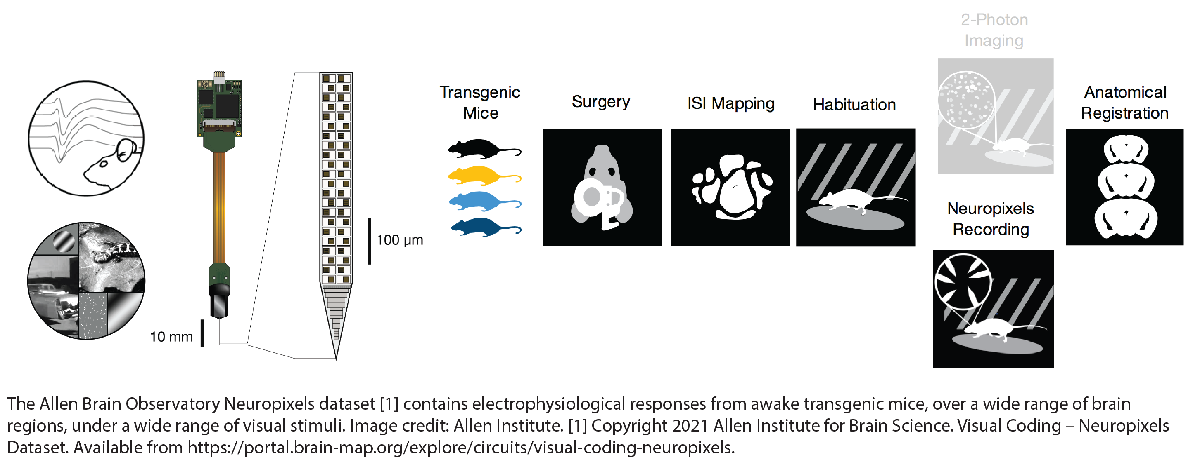

This example shows how to perform some simple analyses of visual responses by neurons in the mouse primary visual cortex using the [Brain Observatory Toolbox](https://github.com/emeyers/Brain-Observatory-Toolbox) (BOT). Neural response properties such as receptive field and orientation tuning are quantified.

The electrophysiology data for individual experimental sessions can be large — on the order of several GBytes for each experimental session. Be aware that running this demo will cause the download of approximately 5GB of data, which may take considerable time. This data will be cached by the toolbox, so that subsequent runs of the demo will be fast.

### Examining Session Spike Firing Statistics Across Units

First, we will use a session and its associated information to examine and compare the firing rates of units across the cortical and sub-cortical regions of the brain.

#### Selecting a “Brain Observatory 1.1” session of interest

The Neuropixels dataset consists of two types of sessions, and each uses a different stimulus set. This demo will use the original "brain_observatory_1.1" session type. More information about the two types of sessions can be found [here](https://allensdk.readthedocs.io/en/latest/_static/neuropixels_stimulus_sets.png), from the Allen SDK documentation [3].

% obtain all sessions in the ephys dataset
sessions = bot.listSessions('ephys');

% obtain all sessions with the desired session_type and then select the first one
desiredSessions = sessions(sessions.session_type == 'brain_observatory_1.1', :);
sess = bot.getSessions(desiredSessions(1, :));

#### Examining unit statistics by brain structure

Now, units can be accessed to compute their firing rates across the different brain regions stored in `.structure_acronyms`, which is derived from the `.info` property.

% get brain regions recorded
disp(sess.structure_acronyms)

    "APN"    "CA1"    "CA3"    "DG"    "LGd"    "LP"    "MB"    "PO"    "PoT"    "VISam"    "VISl"    "VISp"    "VISpm"    "VISrl"    "grey"



% obtain all units in the session in the form of a units table
units = sess.units;

Separate cortical (those beginning with VIS) from subcortical areas:

% separate cortical (VIS) and subcortical areas
corticalIndices = contains(string(units.ephys_structure_acronym), 'VIS');
corticalFiringRates = table2array(units(corticalIndices, "firing_rate"));
subCorticalFiringRates = table2array(units(~corticalIndices, "firing_rate"));

...and plot firing rates of cortical and sub-cortical regions along with some central statistics (medians):

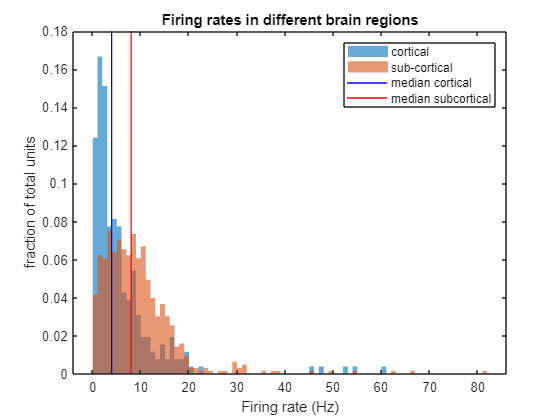

% plot histogram
histogram(corticalFiringRates,'Normalization','probability','BinWidth',1,'EdgeColor','none');hold on
histogram(subCorticalFiringRates,'Normalization','probability','BinWidth',1,'EdgeColor',"none"); hold off

% add statistics
line([median(corticalFiringRates) median(corticalFiringRates)],get(gca,'YLim'),'Color','b')
line([median(subCorticalFiringRates) median(subCorticalFiringRates)],get(gca,'YLim'),'Color','r')
legend({'cortical','sub-cortical','median cortical','median subcortical'})
title('Firing rates in different brain regions')
xlabel('Firing rate (Hz)')
ylabel('fraction of total units')

In this case, the visual cortex has lower firing rates than those observed from the sub-cortical regions. It also appears that the cortex has sparse coding, and the Neural Decoding Toolbox could be used to obtain further information.

### Examining Session Visual Brain Areas and Visual Stimuli

The top layer of the brain is the cortex, and probes are inserted into the primary visual cortex (V1) in these experiments.

#### Identifying visual area brain structures by probe

We examine the brain structures associated with each probe:

% obtain all probes in the session
probes = sess.probes;

% obtain the brain region that each probe examines
disp(probes.ephys_structure_acronyms)

    "APN; CA1; DG; MB; VISam"
    "VISpm; grey"
    "CA1; DG; LP; PO; PoT; VISp"
    "CA1; CA3; DG; LGd; VISl"
    "CA1; CA3; DG; LGd; LP; PO; VISrl"
    "CA1; VISrl"



As shown, each of the first five probes intersects a different visual cortex area.

#### Examining visual stimulus epochs

Each session consists of a sequence of visual stimuli, as illustrated [here](https://allensdk.readthedocs.io/en/latest/_static/neuropixels_stimulus_sets.png) [3] and as described in the behavior tutorial.

% the stimulus_epochs property displays the sequence of visual stimuli
sess.stimulus_epochs

ans = 30×5 timetable
       Time       start_time    stop_time    duration        stimulus_name        stimulus_block
    __________    __________    _________    ________    _____________________    ______________

    13.471 sec      13.471       73.537       60.067     "spontaneous"                 NaN      
    73.537 sec      73.537       985.53          912     "gabors"                        0      
    985.53 sec      985.53       1274.5       288.99     "spontaneous"                 NaN      
    1274.5 sec      1274.5         1573        298.5     "flashes"                       1      
    1573 sec          1573       1574.8       1.7514     "spontaneous"                 NaN      
    

#### Selecting the anteromedial area of the visual cortex

Since we will be looking at orientation selectivity, we want to examine the anterolateral (AL), rostrolateral (RL), or anteromedial (AM) areas of V1 since orientation and direction selectivity are reported to be most pronounced in these areas [4]. We look at the first probe's brain region:

probes.ephys_structure_acronyms(1)

ans = "APN; CA1; DG; MB; VISam"

The first probe examines the AM area of the visual cortex, so we select this probe.

probe = bot.getProbes(probes(1, :));

### Computing the Receptive Field Map for an Individual Unit

Before looking at orientation sensitivity, we will use the Gabor patch stimulus epoch in this session to compute a receptive field map. This epoch can serve as a control that the probe’s units are responsive across the visual field.

% get a full table of individual stimulus presentations
stimuli = sess.stimulus_presentations;

% extract Gabor patches from stimulus set
StimIndices = stimuli(stimuli.stimulus_name=='gabors', :);

#### Examining the Gabor patch stimulus properties

The Gabor patch stimuli have different orientations and are distributed across the visual field in a grid-like manner.

% extract stimulus locations and orientations
StimXloc = unique(StimIndices.x_position);
StimYloc = unique(StimIndices.y_position);
StimOrnt = unique(StimIndices.orientation);

% display stimulus properties
disp("stimulus x pos: " + num2str(StimXloc') + newline ...
    + "stimulus y pos: " + num2str(StimYloc') + newline ...
    + "stimulus orientation: " + num2str(StimOrnt'))

stimulus x pos: -40 -30 -20 -10   0  10  20  30  40
stimulus y pos: -40 -30 -20 -10   0  10  20  30  40
stimulus orientation: 0  45  90


As shown above, there are 81 unique locations and 3 unique orientations. The product of these values yields 243, which is the number of unique stimulus conditions as demonstrated by `length(unique(StimIndices.stimulus_condition_id))`.

We can confirm this by checking that each stimulus condition examines a unique set of parameters {orientation, x position, y position}.

% obtain the parameters associated with each stimulus condition
condParams = table2array(sess.stimulus_conditions(2:244,["orientation" "x_position" "y_position"]));

% find the number of unique sets of parameters
height(unique(condParams,'row'))

ans = 243

As expected, the height equals 243.

#### Examining individual unit firing by visual stimulus condition

First, we obtain a table of the probe's units in order to construct an individual unit object for the first unit in the AM.

% select all units of the probe
probeUnits = probe.units;

% select all units in the AM using logical indexing
probeUnits = probeUnits(probeUnits.ephys_structure_acronym == 'VISam', :);

% obtain a `unit` object for the first unit in the AM
unit = bot.getUnits(probeUnits(1, :));

Then, we examine the spike counts associated with the different Gabor patches for this unit using the `getConditionwiseSpikeStatistics()` method. Since all stimulus conditions are not necessarily repeated in all experiments, some of these are invalid for the current unit and are removed.

% extract spike statistics by stimulus conditions and remove invalid conditions
spkCounts = sess.getConditionwiseSpikeStatistics(StimIndices.stimulus_presentation_id,unit.id);

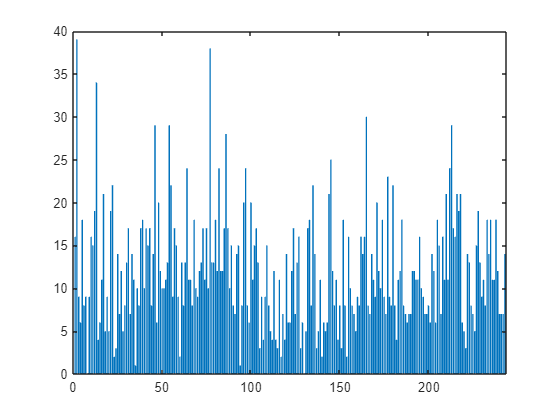

spkCounts = rmmissing(spkCounts);

% plot a bar plot of spike counts by condition number
bar(spkCounts.stimulus_condition_id,spkCounts.spike_count)

#### Computing and visualizing the receptive field map 

We now visualize the receptive field map by looping through the Gabor patches to plot the spike counts for each stimulus location. Note that this is a spatial representation of the spike statistics by condition and averaged over orientations.

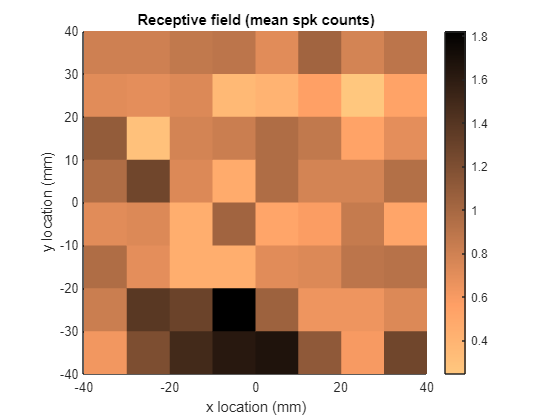

scnt = zeros(length(StimXloc),length(StimYloc));
for ii = 1:length(StimXloc) % loop through stimulus positions
    for jj = 1:length(StimYloc)
        validStimIndices = StimIndices.x_position == StimXloc(ii) & ...
            StimIndices.y_position == StimYloc(jj);
        StimConditionIds = unique(StimIndices.stimulus_condition_id(validStimIndices)); % matching stim conditions
        ValidConditionIds = ismember(spkCounts.stimulus_condition_id,StimConditionIds); % find stim conditions valid for unit
        scnt(ii,jj) = sum(spkCounts.spike_count(ValidConditionIds))/...
            sum(spkCounts.stimulus_presentation_count(ValidConditionIds));
    end
end

% plot the data
surf(StimXloc,StimYloc,scnt)
shading flat
axis square
view([0 90])
cmap = copper();
colormap(cmap(end:-1:1, :));
colorbar
ylabel('y location (mm)')
xlabel('x location (mm)')
title('Receptive field (mean spk counts)')

There appears to be some spatial selectivity towards the bottom, illustrating parafoveal vision, but as expected, the unit is active across the entire visual field.

### Computing a Unit Orientation Tuning Curve 

We now compute an orientation tuning curve to measure the orientation selectivity of this unit from the AM area by using the `"static_gratings"` [stimuli](http://observatory.brain-map.org/visualcoding/stimulus/static_gratings#:~:text=The%20static%20grating%20stimulus%20consists,the%20position%20of%20the%20grating).&text=At%20the%20intersections%20of%20these,corresponding%20to%20a%20different%20phase.).

% identify and select static grating stimuli
stimuli = sess.stimulus_presentations;
staticGratingIndices = stimuli(stimuli.stimulus_name == "static_gratings", :);
stimulusPresentationIds = staticGratingIndices.stimulus_presentation_id;

#### Visualizing temporal response statistics as a peristimulus time histogram (PSTH) 

To choose a selective time window for the response, a peri-stimulus time histogram (PSTH) of several unit responses from the same probe will first be created. Averaging across units is necessary to correct for potential outliers among the spike counts, and the unit responses are measured by the `getPresentationwiseSpikeCounts()` method.

% build a PSTH (enter the number of trials to use for PSTH calculation,
% more trials will require a longer computational time)
nPsthUnits = str2double("2"); % please enter a number between 2 and 20
timeBins = 0:25e-3:500e-3;
psth = sess.getPresentationwiseSpikeCounts(timeBins, stimulusPresentationIds, unit.probe.units{1:nPsthUnits, 'id'});

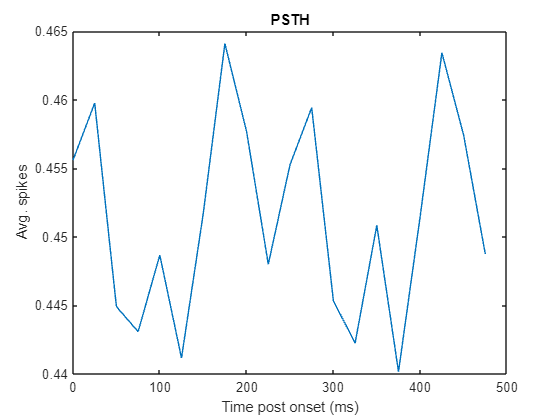


% plot the PSTH
plot(timeBins(1:end-1) * 1e3, mean(psth, [2 3]));
xlabel('Time post onset (ms)');
ylabel('Avg. spikes');
title('PSTH');

Note that using the maximum number of trials, 20, leads to a smoother plot with two well-defined peaks but requires a much longer computational time.

#### Computing and visualizing a unit orientation tuning curve

Then, the particular unit can be tuned to the orientation of a visual stimulus. The response window corresponds to a section of the PSTH with significant spiking peaks.

% compute stimulus responses after selecting response window
respWindow = [250 500] * 1e-3;
responses = sess.getPresentationwiseSpikeCounts(respWindow, stimulusPresentationIds, unit.id);

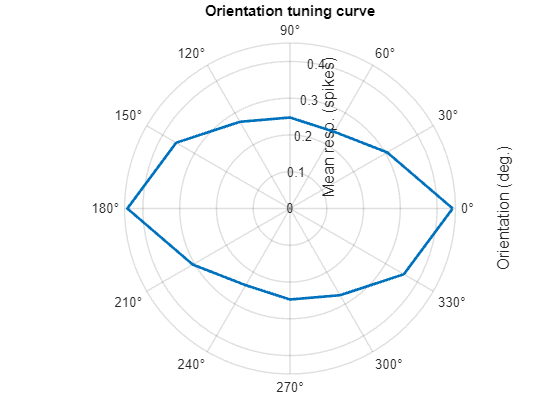


% collect stimuli by stimulus orientation
stimOrientation = staticGratingIndices.orientation;
[condOrientation, ~, oriIndex] = unique(stimOrientation);
blanks = isnan(stimOrientation);
oriIndex(blanks) = 7;

% calculate mean and std. dev. of responses per stimulus orientation
respMean = accumarray(oriIndex, responses, [], @mean);
respStd = accumarray(oriIndex, double(responses), [], @std);

% plot an orientation tuning curve
orientation = deg2rad(condOrientation);
orientation = [orientation(1:6); orientation(1:6) + pi; orientation(1)];
polarplot(orientation, respMean([1:6 1:6 1]), 'LineWidth', 2);
a = gca;
a.RAxis.Label.String = 'Mean resp. (spikes)';
a.ThetaAxis.Label.String = 'Orientation (deg.)';
title('Orientation tuning curve')

This unit from the AM area is tuned along the 0-180 degree axis, but its orientation selectivity is not very sharp.

### Examining Probe Local Field Potential Data

Local field potential (LFP) and current source density (CSD) measurements access low frequency data and are accessed using methods from the `probe` objects, as described in the tutorial. We use the probe object created earlier.

#### Viewing LFP data along a probe

Probe LFP data is displayed as a timetable with time values and arrays of local field potentials as the values under columns.

% view head of timetable for LFP data
lfpTimetable = probe.lfpData;
head(lfpTimetable)

       Time       LocalFieldPotential
    __________    ___________________

    28.824 sec        1×93 single    
    28.825 sec        1×93 single    
    28.826 sec        1×93 single    
    28.826 sec        1×93 single    
    28.827 sec        1×93 single    
    28.828 sec        1×93 single    
    28.829 sec        1×93 single    
    28.83 sec         1×93 single    



#### Visualizing CSD along a probe

CSD data is computed from the probe LFP data [5] and can be plotted.

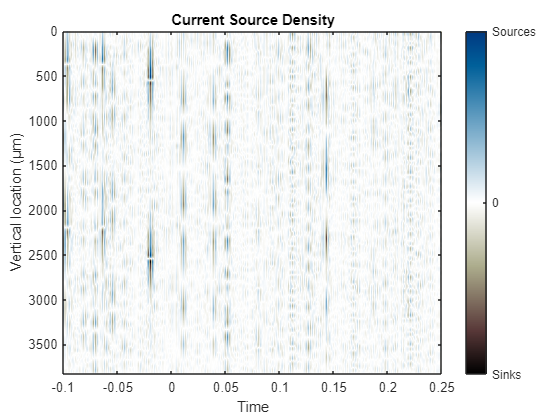

% extract CSD data for the probe
tt = probe.csdData.data; % timetable 
vposns = probe.csdData.verticalPositions;

% plot the CSD data
figure, imagesc(seconds(tt.Time), vposns, table2array(tt));
colormap(vertcat(flipud(1-bone()), 1-copper()));
max_amp = max(abs(caxis));
colorbar('Ticks',[-max_amp,0,max_amp],'Ticklabels',{'Sinks','0','Sources'})
caxis([-1 1] * max_amp);
xlabel('Time');
ylabel('Vertical location (µm)');
title('Current Source Density');

### Learn More

For more detailed guidance on how to use the Brain Observatory Toolbox with the Visual Coding Neuropixels dataset, see the [Ephys Tutorial](matlab:open('..\tutorials\EphysTutorial.mlx')).

### References

[1] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 

[2] Copyright 2019 Allen Institute for Brain Science. Visual Coding Neuropixels. Available from: [portal.brain-map.org/explore/circuits/visual-coding-neuropixels](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels).

[3] Copyright 2019 Allen Institute for Brain Science. Visual Coding Neuropixels. Available from: [https://allensdk.readthedocs.io/en/latest/_static/neuropixels_stimulus_sets.png](https://allensdk.readthedocs.io/en/latest/_static/neuropixels_stimulus_sets.png).

[4] Marshal, J.H., Garrett, M.E., Nauhaus, I., and Callaway, E.M. (2011). Functional Specialization of Seven Mouse Visual Cortical Areas. *Neuron* 72 (6): 1040. [https://dx.doi.org/10.1016%2Fj.neuron.2011.12.004](https://dx.doi.org/10.1016%2Fj.neuron.2011.12.004).

[5] Copyright 2019 Allen Institute for Brain Science. Visual Coding Neuropixels. Available from: [https://allensdk.readthedocs.io/en/latest/_static/examples/nb/ecephys_lfp_analysis.html](https://allensdk.readthedocs.io/en/latest/_static/examples/nb/ecephys_lfp_analysis.html).